clc;clear;

Define constants

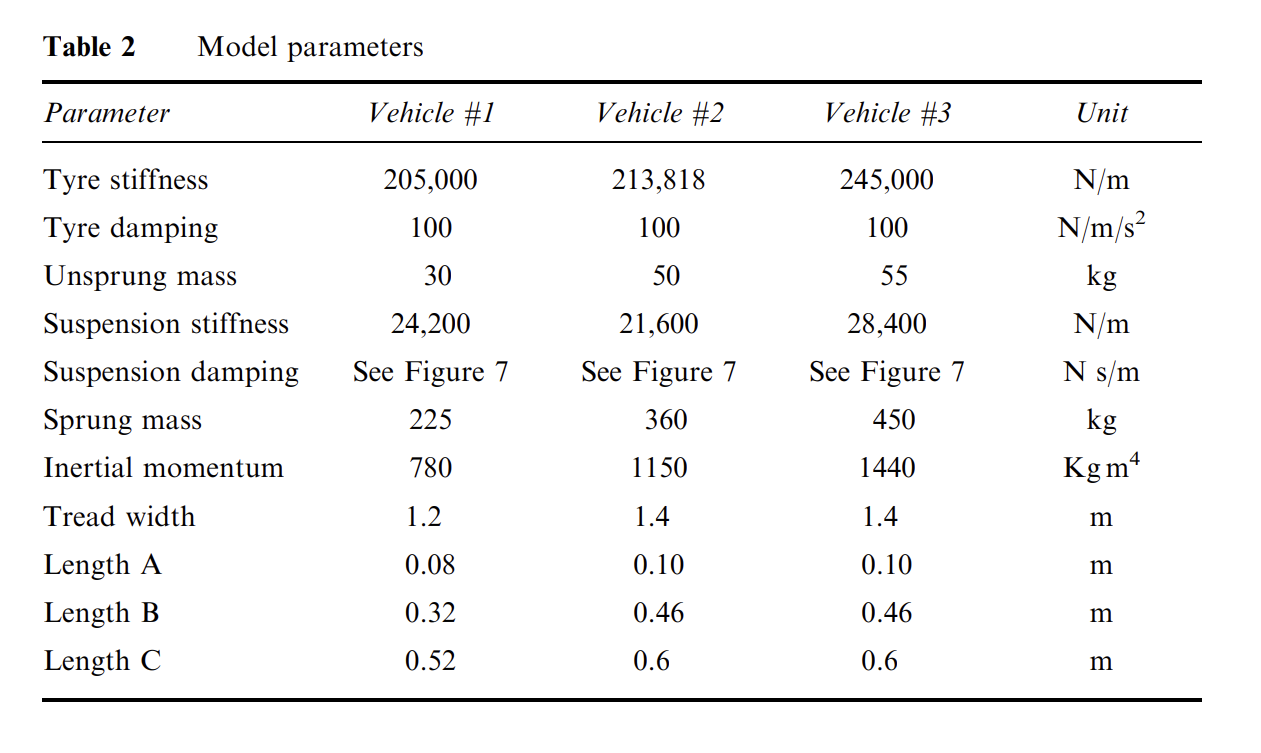

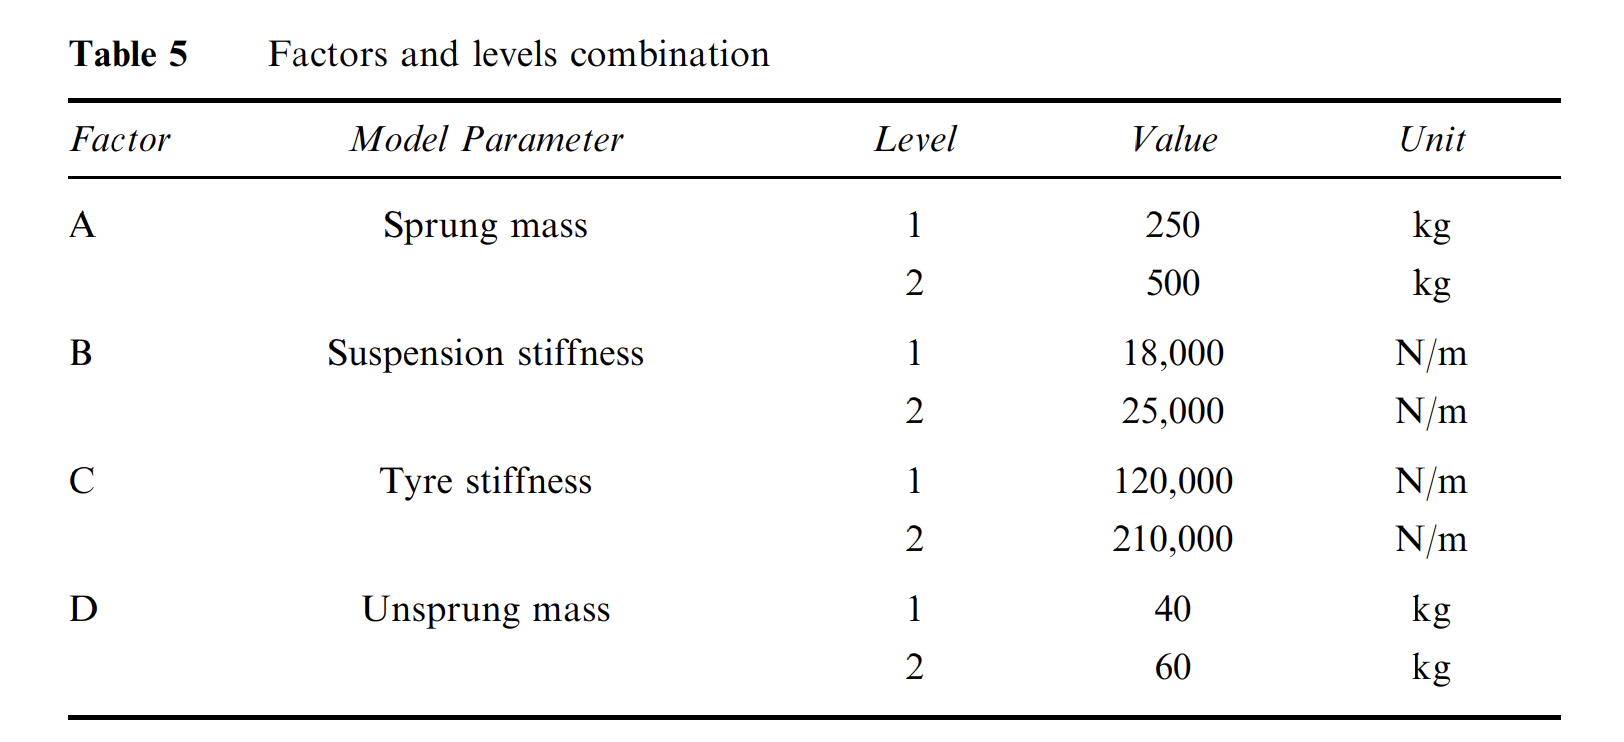

DOI:[10.1504/IJVD.2005.007623](http://dx.doi.org/10.1504/IJVD.2005.007623)

M1 = 1300/4; % ¼ Mass of car
M2 = 225; % Suspension Mass
k1 = 24200; % Spring constant of Suspension System
k2 = 205000; % Spring constant of Wheel and tire
c1 = 350; % Damping constant of Suspension System
c2 = 1500; % Damping constant of Wheel and tire

Define the Transfer Function

s = tf('s');
% TF from F to X1-X2
P1 = ((M1+M2)*s^2 + c2*s + k2) / ((M1*s^2 + c1*s + k1) * (M2*s^2 + (c1+c2)*s + (k1+k2)) - (c1*s + k1)^2);
% TF from W to X1-X2
P2 = (-M1*c2*s^3 - M1*k2*s^2) / ((M1*s^2 + c1*s + k1) * (M2*s^2 + (c1+c2)*s + (k1+k2)) - (c1*s + k1)^2);
% Block A
A = (-M1*c2*s^3 - M1*k2*s^2) / ((M1+M2)*s^2 + c2*s + k2);

Check DC-gain and Step Response of Plant1 and Plant2

dcgain(P1)

ans = 4.1322e-05

dcgain(P2)

ans = 0

pole(P1)

ans =   -4.2003 +31.7653i
  -4.2003 -31.7653i
  -0.4493 + 8.1165i
  -0.4493 - 8.1165i


zero(P1)

ans =   -1.3636 +19.2579i
  -1.3636 -19.2579i


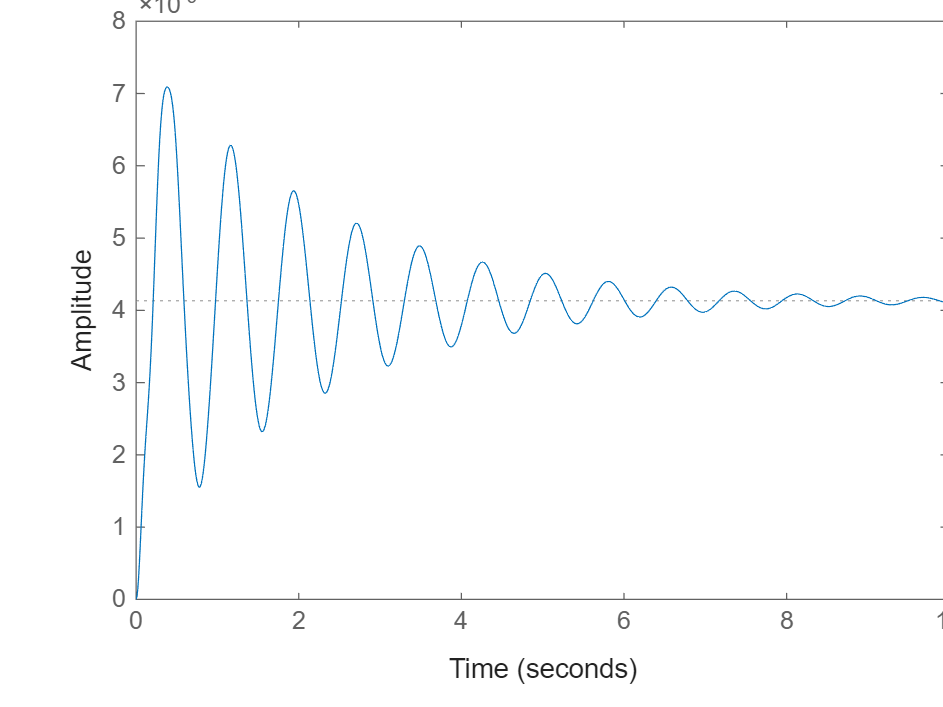

t=0:0.01:10;
step(P1,t)
title('Open-Loop Step Response of Plant 1')

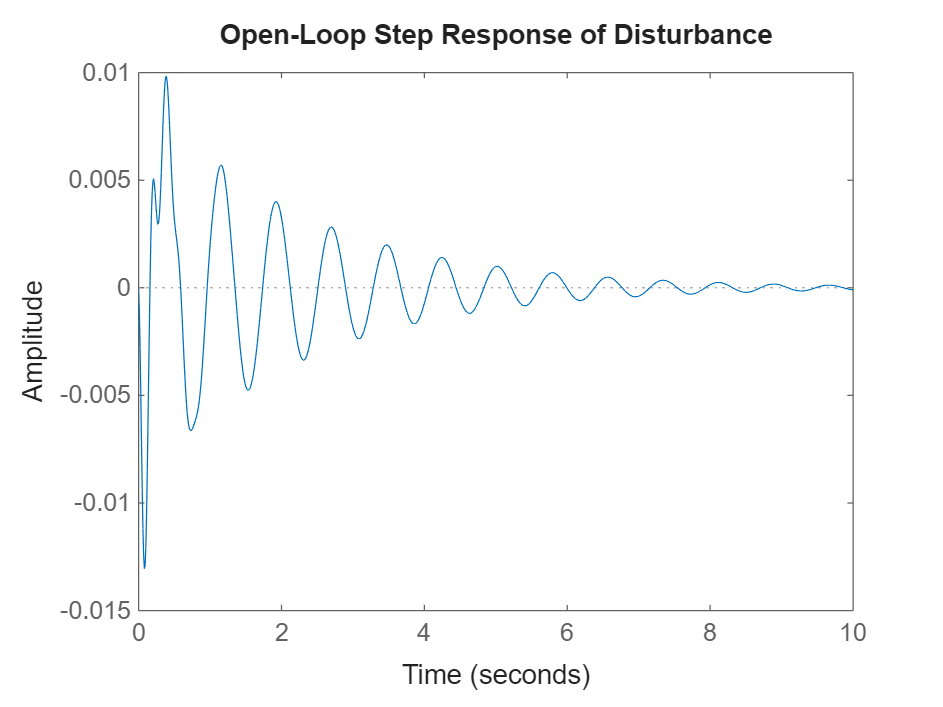

step(0.01*P2,t)
title('Open-Loop Step Response of Disturbance')

Controller Setting

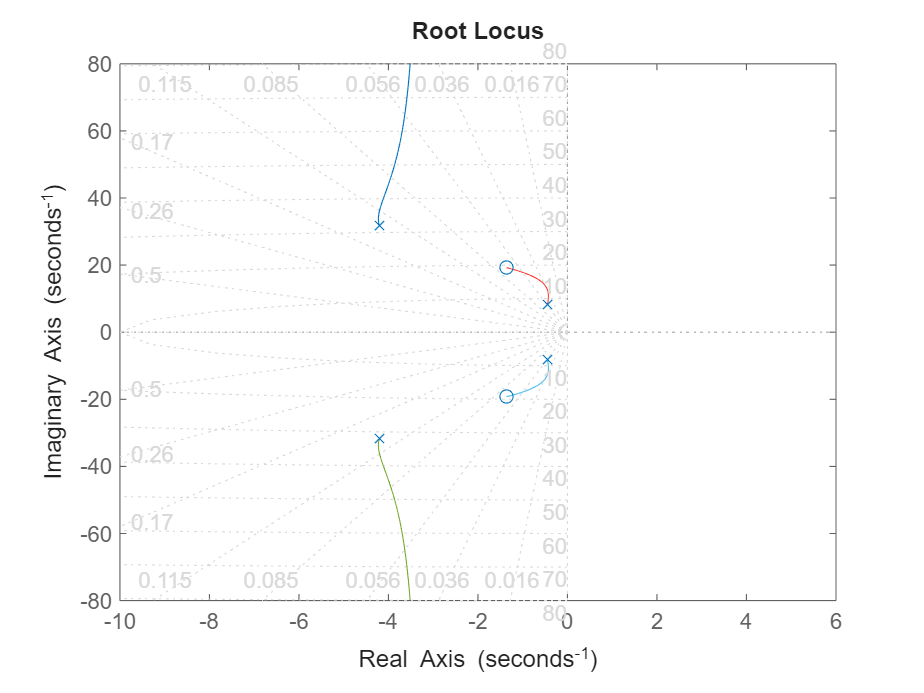

% Check root locus of Plant 1
rlocus(P1)
z = (1-0.25)*0.6;
t_r = 4.6/5;
sgrid(z,t_r)


% Closed-Loop with Controller
numc = [0.59^2 0.95 1];
denc = conv([1 20], [1 30]);
C = tf(numc ,denc)


C =
 
  0.3481 s^2 + 0.95 s + 1
  -----------------------
     s^2 + 50 s + 600
 
Continuous-time transfer function.
Model Properties


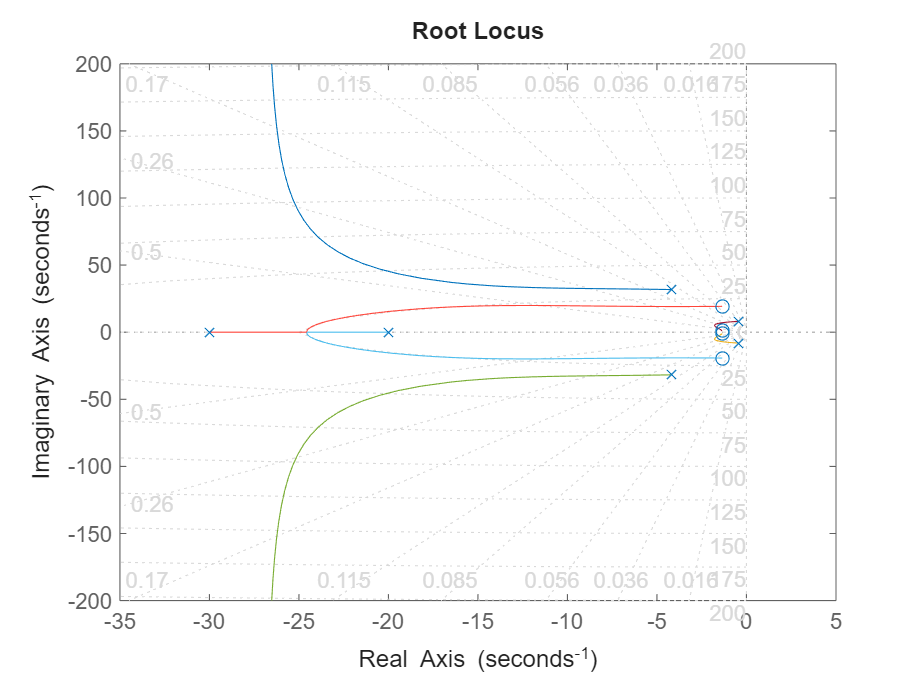

rlocus(C*P1)
sgrid(z,t_r)

Select a point in the graphics window


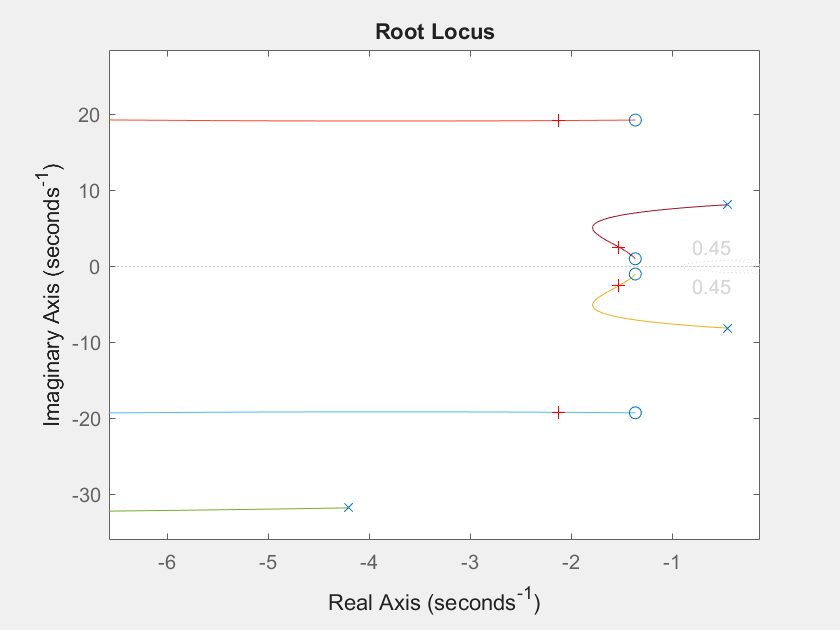

selected_point = -1.5010 + 2.5408i

k = 6.2814e+06

poles = 1.0e+02 *

  -0.2600 + 1.3100i
  -0.2600 - 1.3100i
  -0.0212 + 0.1919i
  -0.0212 - 0.1919i
  -0.0153 + 0.0254i
  -0.0153 - 0.0254i



%[k,poles]=rlocfind(C*P1)

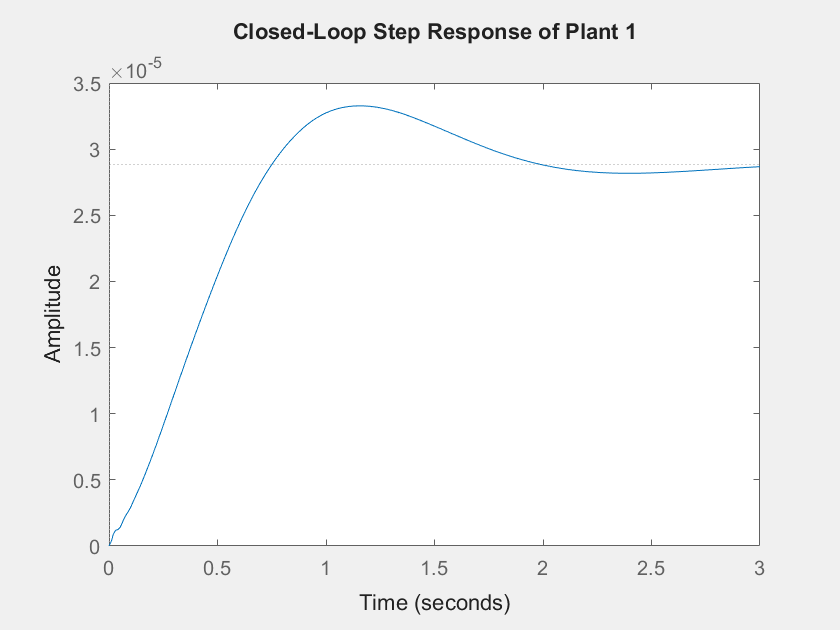

k = 6.2814e+06;
t=0:0.01:3;
sys_1 = feedback(P1,k*C);
step(sys_1,t)
title('Closed-Loop Step Response of Plant 1')

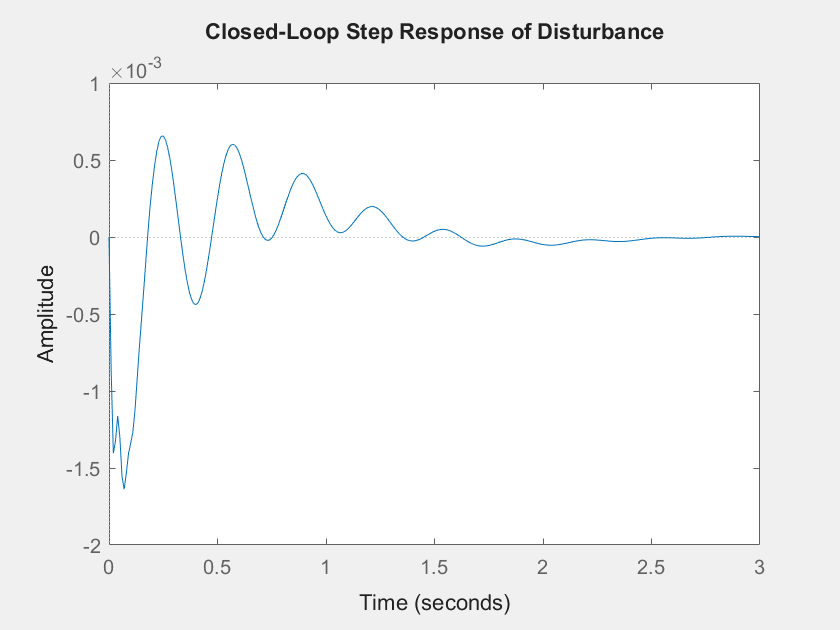

sys = A*feedback(P1,k*C);
step(0.01*sys,t)
title('Closed-Loop Step Response of Disturbance')

Bode Plot and Lead Control

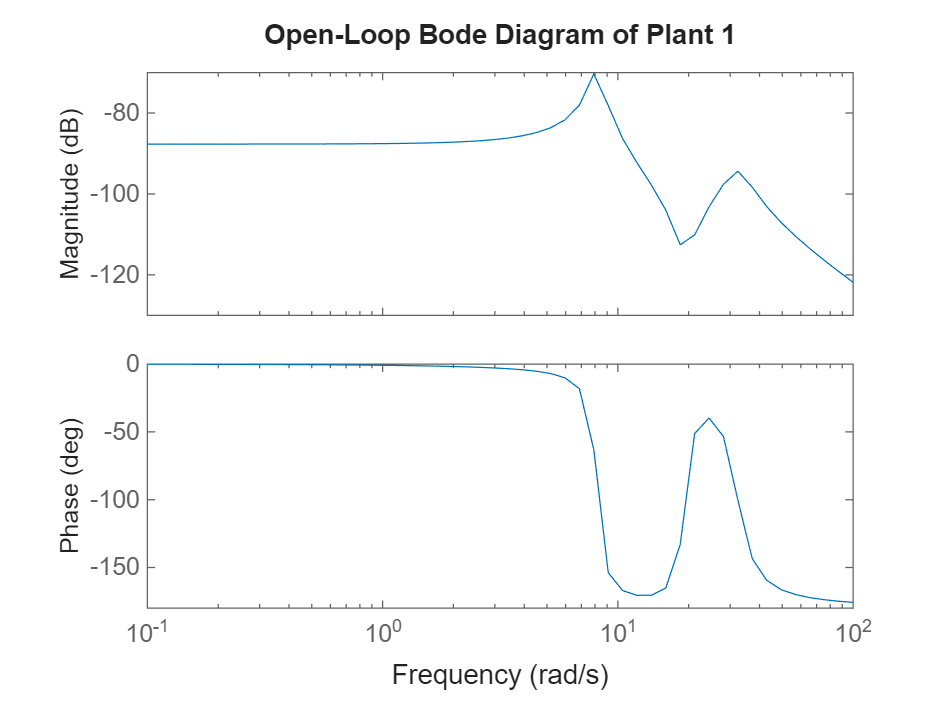

w = logspace(-1,2);
bode(P1,w)
title('Open-Loop Bode Diagram of Plant 1')

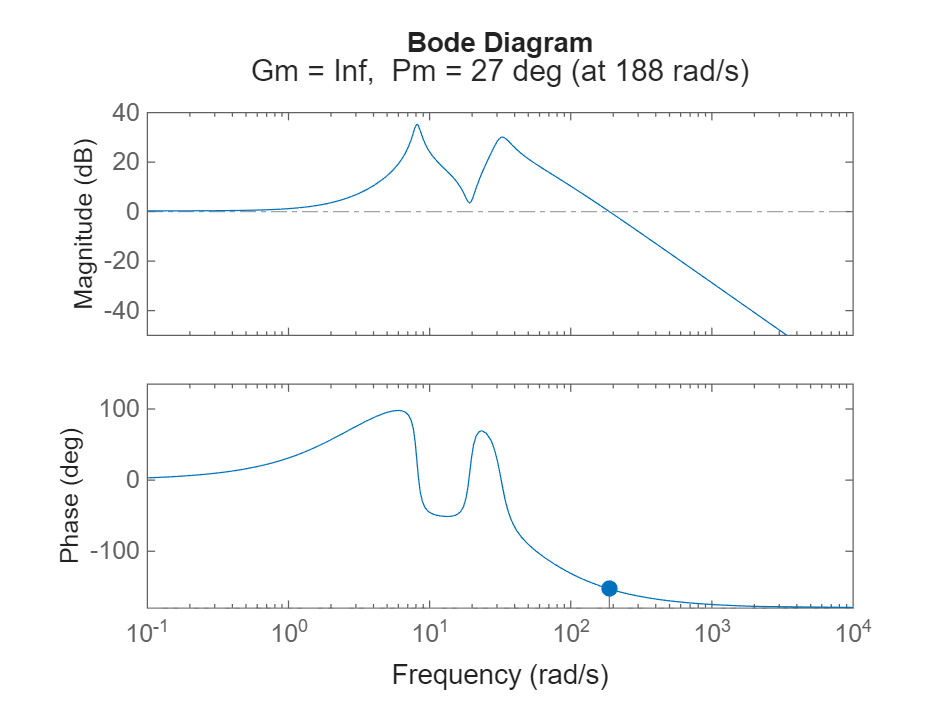

K = 25000;
a = (1-sin(60/180*pi))/(1+sin(60/180*pi));
w=12;
T=1/(w*sqrt(a));A
aT=sqrt(a)/w;
numc = conv([T 1], [T 1]);
denc = conv([aT 1], [aT 1]);
C = tf(numc,denc);
margin(K*C*P1)

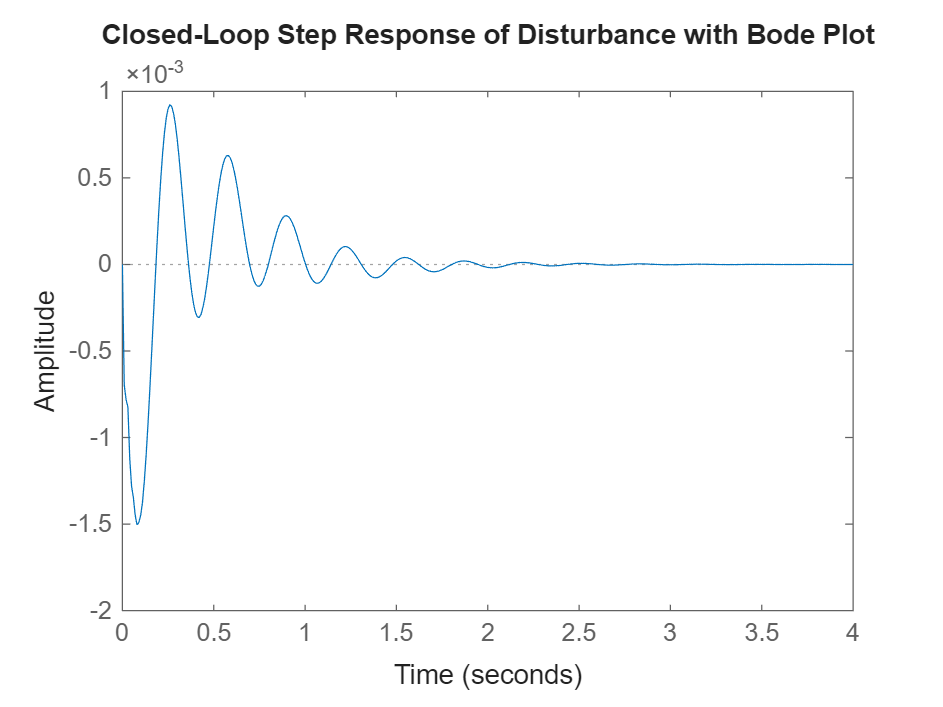

sys = A*feedback(P1,K*C);
t=0:0.01:4;
step(0.01*sys,t)
title('Closed-Loop Step Response of Disturbance with Bode Plot')

Using PID Tuner

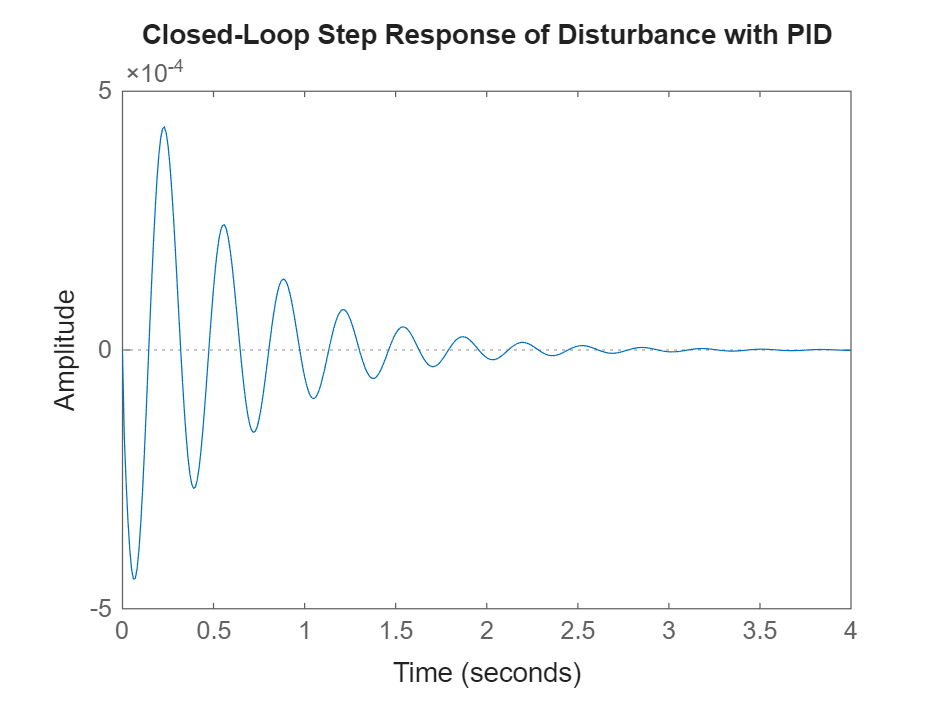

% pidTuner(P1,'PID')
Kd = 110638;
Kp = 272803;
Ki = 9950;
C = pid(Kp,Ki,Kd);
sys = A*feedback(P1,C);
t=0:0.01:4;
step(0.01*sys,t)
title('Closed-Loop Step Response of Disturbance with PID')